# 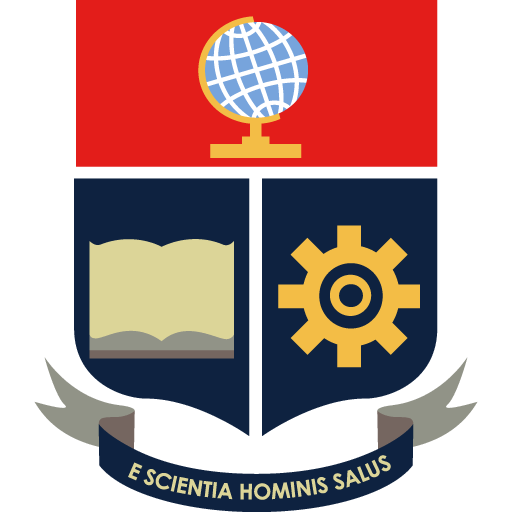

# **Cambio de Formación**

 
Goal=0.030;
mov=0;
ant=0;
antd=0;
ind1=1;
t_sim2=100;
option=6;
if server.NumBytesAvailable~=0
data=read(server,server.NumBytesAvailable,"uint8");
option=data(length(data));
end

### `Posiciones en las Formaciones`

%%%Código para Figura con las posiciones en las Formaciones
% d2=1;
% figure('Name','Formaciones','NumberTitle','off');
% subplot(2,3,1)
% plot(0,d2,'bo',0,0,'bo',0,-d2,'bo',0,0,'gx')
% hold on; line([0,0],[d2,-d2],'Color',[1 0.41 0.16],'LineStyle','--')
% ax = gca;ax.YAxis.TickValues = ax.XAxis.TickValues;
% title('1 Columna')
% grid on
% subplot(2,3,4)
% plot(d2,0,'bo',0,0,'bo',-d2,0,'bo',0,0,'gx')
% hold on; line([-d2,d2],[0,0],'Color',[1 0.41 0.16],'LineStyle','--')
% ax = gca;ax.YAxis.TickValues = ax.XAxis.TickValues;
% title('2 Fila')
% grid on
% %V
% subplot(2,3,2)
% plot(d2,d2,'bo',-d2,d2,'bo',0,-d2,'bo',0,0,'gx')
% hold on;line([0,d2],[-d2,d2],'Color',[1 0.41 0.16],'LineStyle','--');line([0,-d2],[-d2,d2],'Color',[1 0.41 0.16],'LineStyle','--')
% ax = gca;ax.YAxis.TickValues = ax.XAxis.TickValues;
% title('3 Formación V')
% grid on
% subplot(2,3,5)
% plot(d2,-d2,'bo',-d2,-d2,'bo',0,d2,'bo',0,0,'gx')
% hold on;line([0,-d2],[d2,-d2],'Color',[1 0.41 0.16],'LineStyle','--');line([0,d2],[d2,-d2],'Color',[1 0.41 0.16],'LineStyle','--')
% ax = gca;ax.YAxis.TickValues = ax.XAxis.TickValues;
% title('4 Formación V inversa')
% grid on
% %L
% subplot(2,3,3)
% plot(-d2,d2,'bo',-d2,-d2,'bo',d2,-d2,'bo',0,0,'gx')
% hold on;line([-d2,d2],[-d2,-d2],'Color',[1 0.41 0.16],'LineStyle','--');line([-d2,-d2],[-d2,d2],'Color',[1 0.41 0.16],'LineStyle','--')
% ax = gca;ax.YAxis.TickValues = ax.XAxis.TickValues;
% title('5 Formación L')
% grid on
% subplot(2,3,6)
% plot(-d2,-d2,'bo',d2,d2,'bo',d2,-d2,'bo',0,0,'gx')
% hold on;line([-d2,d2],[-d2,-d2],'Color',[1 0.41 0.16],'LineStyle','--');line([d2,d2],[-d2,d2],'Color',[1 0.41 0.16],'LineStyle','--')
% ax = gca;ax.YAxis.TickValues = ax.XAxis.TickValues;
% title('6 Formación L inversa')
% grid on

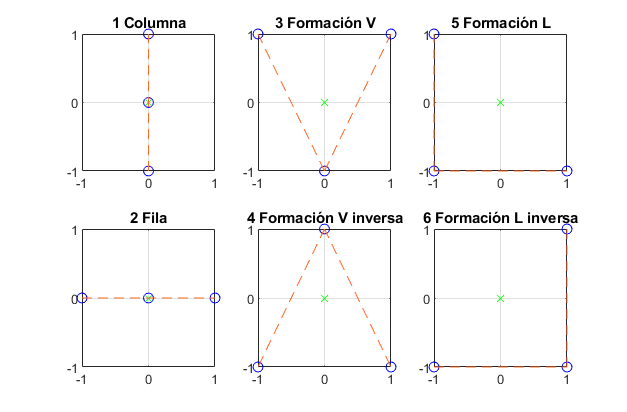

Opciones de cambio de formación:

1.- Columna                4.- Formación V inversa

2.- Fila                         5.- Formación L

3.- Formación V           6.- Formación L inversa

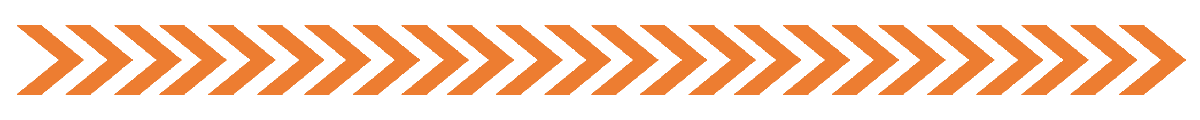

%(Inicio) Elección para ejecutar o regresar a menu
while option~=4
    option=6;
if server.NumBytesAvailable~=0
    data=read(server,server.NumBytesAvailable,"uint8");
    option=data(length(data));
end
printStatus (ind1)
if option==3%FistRef1
%(Ref1)Ejecución de la interfaz de Simulink y cambio de formación
%reinicio de vectores para la ejecucion

posicionx1=zeros(1,100);posiciony1=zeros(1,100);
posicionx2=zeros(1,100);posiciony2=zeros(1,100);
posicionx3=zeros(1,100);posiciony3=zeros(1,100);
vectrx1=zeros(1,100);vectry1=zeros(1,100);
vectrx2=zeros(1,100);vectry2=zeros(1,100);
vectrx3=zeros(1,100);vectry3=zeros(1,100);
i=1;
j=1;
k=1;
mn=1;
ref1=1;

while option ~=4 %open
    %lectura del gesto
    if server.NumBytesAvailable~=0
        data=read(server,server.NumBytesAvailable,"uint8");
        option=data(length(data));
        ref1=2;%indica que ya se ha leido un gesto tras entrar
%         switch option
%             case 1
%                 gesim="1.png";gesto="Gesto - Wave out";
%             case 2
%                 gesim="2.png";gesto="Gesto - Wave in";
%             case 3
%                 gesim="3.png";gesto="Gesto - zeros(1,5)Fist";
%             case 4
%                 gesim="4.png";gesto="Gesto - Open";
%             case 5
%                 gesim="5.png";gesto="Gesto - Pinch";
%             otherwise
%                 gesim="6.png";gesto="Relajado - No Gesture";
%         end    
       %d es la distancia que puede tener cada agente respecto al Lider Virtual
%          antop=option;
    else
        if ref1==1
            option=0;
        end
    end
    %fin de lectura del gesto
option;
open('FormationControl.slx');
vars=sim('FormationControl');
option=vars.option(length(vars.option));
rx1=vars.h(end,1);
ry1=vars.h(end,2);
rx2=vars.h(end,3);
ry2=vars.h(end,4);
rx3=vars.h(end,5);
ry3=vars.h(end,6);
d=vars.d(end);
form=vars.form(end);

if option==3%Fist
    
    if ant~=form||antd~=d
        ant=form;
        antd=d;
        fprintf('*-_-_-_-_-_-_-_-_-_-_-*\n')
        disp("Simulación iniciada")
        open('Mtest6.slx')
        simform=sim("Mtest6.slx");
        open('menu_op1_formation.mlx')
        disp("Simulación terminada en:")
        tiempo=simtime(end)/0.1 % valor en paced simulation
        tiempoROS=rostime(end)-rostime(1)    
        % Resultados:
        run results_op1.m
    end
    %(Fist End)fin de cambio de formación
    %guardar datos
    vectrx1(i)=x+rx1;vectry1(i)=y+ry1;
    vectrx2(i)=x+rx2;vectry2(i)=y+ry2;
    vectrx3(i)=x+rx3;vectry3(i)=y+ry3;
    i=i+1;
    for jj=1:length(PosX1)
    posicionx1(j)=PosX1(jj);
    posiciony1(j)=PosY1(jj);
    j=j+1;
    end
    for kk=1:length(PosX2)
    posicionx2(k)=PosX2(kk);
    posiciony2(k)=PosY2(kk);
    k=k+1;
    end
    for mm=1:length(PosX3)
    posicionx3(mn)=PosX3(mm);
    posiciony3(mn)=PosY3(mm);
    mn=mn+1;
    end
    ang=0;%forma sin giros

end

%(Ref1 End)fin de contenido de while
end
open('menu_op1_formation.mlx')
option=6;
ind1=2;
ant=0;
% Graficar los movimientos de esta ejecucion, se reinicia los vectores
if ~(posicionx1(1:100)==zeros(1,100))
figure
    plot(x,y,'gx','DisplayName','Líder Virtual')
    hold on
    plot(posicionx1,posiciony1,'r','DisplayName','Robot 1')
    plot(posicionx2,posiciony2,'c','DisplayName','Robot 2')
    plot(posicionx3,posiciony3,'m','DisplayName','Robot 3')
    plot(posicionx1(1),posiciony1(1),'b^','DisplayName','Posición Inicial')
    plot(posicionx2(1),posiciony2(1),'b^','HandleVisibility','off')
    plot(posicionx3(1),posiciony3(1),'b^','HandleVisibility','off')
    plot(vectrx1,vectry1,'bo','DisplayName','Posiciones de formación')
    plot(vectrx2,vectry2,'bo','HandleVisibility','off')
    plot(vectrx3,vectry3,'bo','HandleVisibility','off')
    xlabel('Posición en X [m]')
    ylabel('Posición en Y [m]')
    legend('Location','northeastoutside')
    title('Cambios de formación realizados')
end
%(FistRef1 End)
end

%(Inicio End)
end
ant=0;
antd=0;
antop=0;
aux=0;
open("menu.mlx")


function printStatus (ind)
     if ind == 1
        txt='Para empezar haga el gesto Fist o su comando equivalente\n          ';
         fprintf('Para empezar haga el gesto Fist o su comando equivalente\n          ');
         for i=1:strlength(txt)
             fprintf('\b');
         end
     else
        % Each \b removes one character from the previous fprintf.
        txt='Para cambio de formación realizar Fist\nPare regresar al menú realizar Open\n          ';
        fprintf('Para cambio de formación realizar Fist\nPare regresar al menú realizar Open\n          ');
        for i=1:strlength(txt)
             fprintf('\b');
         end
     end
end
